clc
clear all
close all

# System Identification and Speed Control of a DC Servo Motor

## Quanser QUBE-Servo Dynamic Plant:

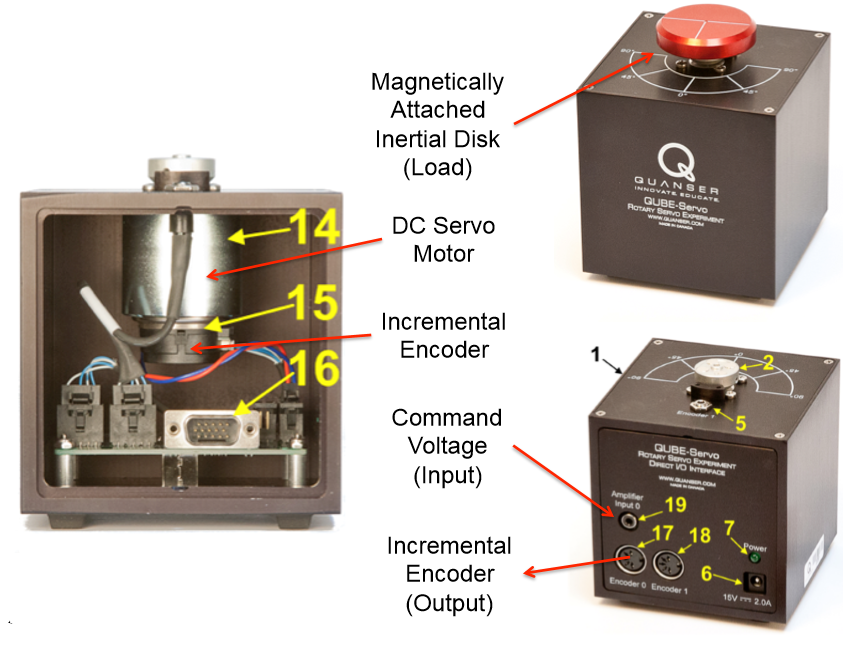

## Definition of System States and Parameters:

#### Mechanical Dynamics:

J = Total rotational inertia in $\mathrm{kg}\ldotp$$m^2$

$\beta$ = Total rotational damping in $\frac{\left(N\ldotp m\ldotp s\right)}{\mathrm{rad}}$

$K_T$ in $\frac{N\ldotp m}{A}$ = $K_V$ in $\frac{V\ldotp s}{\mathrm{rad}}$ = Motor constant 

$\omega$ = $\frac{d\theta }{\mathrm{dt}}$ = Rotational frequency in $\frac{\mathrm{rad}}{s}$

$\theta \;$= Rotational position in rad

#### Electrical Dynamics:

L = Motor Inductance in Henry (H)

R = Motor Resistance in ohms ($\Omega$)

i = Motor current in Amperes (A)

V = input voltage in Volts (V)

### Equations of Motion:

#### Mechanical Dynamics:


$$\left(\mathrm{Js}+\beta \right)\omega =K_T i$$



$$\Rightarrow \omega =\frac{K_T i}{\left(\mathrm{Js}+\beta \right)}\;$$


#### Electrical Dynamics:


$$\left(\mathrm{Ls}+R\right)i+K_V \omega =V$$


**Note**: Both the Mechanical and electrical dynamics are coupled through Motor Constants.

The open-loop motor transfer is like : $P_{\mathrm{motor}} \left(s\right)=\frac{\omega \left(s\right)}{V\left(s\right)}=\frac{\mathrm{output}}{\mathrm{input}}$

### Allied Motion CL40 Series Coreless DC Servo Motor with datasheet:

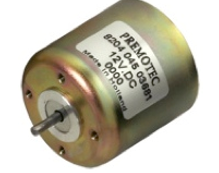

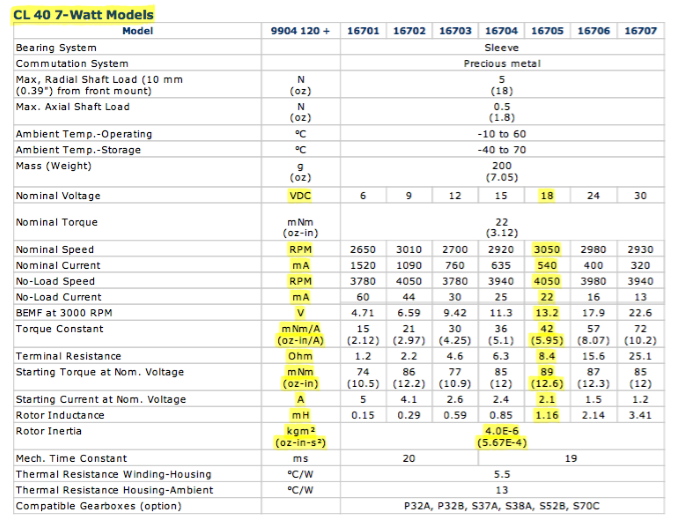

Where, $J=J_{\mathrm{motor}} +J_{\mathrm{disk}} +J_{\mathrm{hub}}$

Magnetically attached disk, $J_{\mathrm{disk}}$ = 0.6$e^{-6} \;\;\mathrm{kg}\ldotp m^2$

Hub on Motor shaft, $J_{\mathrm{hub}}$= 2$e^{-5} \;\;\mathrm{kg}\ldotp m^2$


$$\beta =1e^{-6} \;\frac{N\ldotp m\ldotp s}{\mathrm{rad}}$$


#### Actual Open-loop plant looks like:

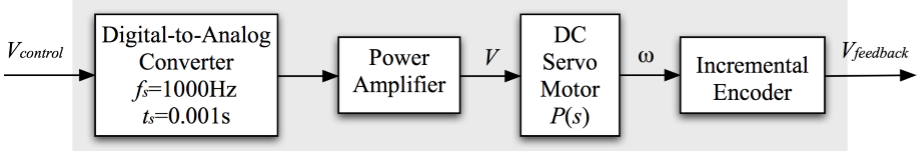

As a result we need to add additional subsystem models to our open loop plant like:

**DAC** - A pure delay of one sample period (ts) and has a gain of 1.0

**Power Amplifier** - Has a gain og 0.0578 volt/volt (No dynamics)

**Incremental Encoder**: A 2nd order 95 Hz unity gain low-pass filter

# Model Development

## Analytic Open loop motor model Transfer function:

% 1a
syms beta J_disk J_hub J_motor J_net K_T K_V R L I omega V s
J_net = J_disk + J_hub + J_motor;   % Total Rotational inertia in kg.m^2

omega = (K_T)*I/(J_net*s + beta);   % Output
V = (L*s + R)*I + K_V*omega;        % Input

% Numerator of the transfer function i.e. the output
num = omega;
disp(' The numerator of the transfer function is: ');

 The numerator of the transfer function is: 


disp(num);

$$\frac{\text{I}\,K_{T}}{\beta +s\,\left(J_{\mathrm{disk}}+J_{\mathrm{hub}}+J_{\mathrm{motor}}\right)}$$


% Denominator of the transfer function i.e. the input
denom = V;
disp(' The denominator of the transfer function is: ');

 The denominator of the transfer function is: 


disp(denom);

$$\text{I}\,\left(R+L\,s\right)+\frac{\text{I}\,K_{T}\,K_{V}}{\beta +s\,\left(J_{\mathrm{disk}}+J_{\mathrm{hub}}+J_{\mathrm{motor}}\right)}$$


t_f = num/denom;
disp(' The transfer function is: ');

 The transfer function is: 


disp(t_f);

$$\frac{\text{I}\,K_{T}}{\left(\text{I}\,\left(R+L\,s\right)+\frac{\text{I}\,K_{T}\,K_{V}}{\beta +s\,\left(J_{\mathrm{disk}}+J_{\mathrm{hub}}+J_{\mathrm{motor}}\right)}\right)\,\left(\beta +s\,\left(J_{\mathrm{disk}}+J_{\mathrm{hub}}+J_{\mathrm{motor}}\right)\right)}$$

## Defining Parameters

beta = 1E-6;                        % Total Rotational damping in (N.m.s)/rad
J_disk = 0.6E-6;                    % Magnetically attached disk in kg.m^2
J_hub = 2E-5;                       % Hub on motor shaft in kg.m^2
J_motor = 4E-6;                     % Rotor intertia in kg.m^2
K_T = 42E-3;                        % Motor constant in N.m/A
K_V = K_T;                          % Motor constant in V.s/rad
R = 8.4;                            % Motor Resistance in ohms
L = 1.16E-3;                        % Motor Inductance in Henry
I = 540E-3;                         % Motor current in Amperes (A)

## LTI Transfer Function object with Parametric Values

% 1b

currentPrecision = digits;
digitsOld = digits(4); % Changing the precision for the no of places upto which I want the solution 

% subs used to find the solution after substituting numeric values to the
% symbolic variables
% double used to convert from symbolic array to numeric array, in order to use it in further computations
num_parametric = vpa(subs(num));
disp(' The numerator of the transfer function is: ');

 The numerator of the transfer function is: 


disp(num_parametric);

$$\frac{0.02268}{2.46e-5\,s+1.0e-6}$$


denom_parametric = vpa(subs(denom));
disp(' The denominator of the transfer function is: ');

 The denominator of the transfer function is: 


disp(denom_parametric);

$$0.0006264\,s+\frac{0.0009526}{2.46e-5\,s+1.0e-6}+4.536$$


% Simplify used to further reduce the equation into a naturally readable
% form
t_f_parametric = simplify(vpa(subs(t_f)));
disp(' How the transfer function looks like: ');

 How the transfer function looks like: 


disp(t_f_parametric);

$$\frac{5.25e+9}{3567.0\,s^{2}+2.583e+7\,s+2.216e+8}$$


% Using the above coefficients to put it in a non symbolic form usable by
% other subsystems
Final_num = [5.25e+9];
Final_denom = [3567 2.583e+7 2.216e+8];
motor = tf(Final_num,Final_denom);
disp(' The transfer function is: ');

 The transfer function is: 


disp(motor);

  tf with properties:

       Numerator: {[0 0 5.2500e+09]}
     Denominator: {[3567 25830000 221600000]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
              Ts: 0
        TimeUnit: 'seconds'
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]



## Remaining Subsystem LTI Transfer Function objects

% 1c
% Digital to Analog Converter
ts = 0.0001; % One Sample Period (Time Step)
dac = tf(1,1,'Inputdelay' , ts);

% 1d
% Low pass filter on the encoder
[lpfnum, lpfden] = butter(2,2*pi*95, 's');
lpf = tf(lpfnum, lpfden);

% Power Amplifier
Kpwramp = 0.0578;

% 1e
% Complete Cascade combination of dynamic LTI objects above including power
% amplifier gain
plant = dac * Kpwramp * motor * lpf;

# Time Domain Validation

**System ID experiment was already done:**

- And thus the Data acquisition application was used to collect excitation data (Vexc) and noisy response data (Vfeedback)

- Experimental data was collected for 60 seconds @ 1000 Hz

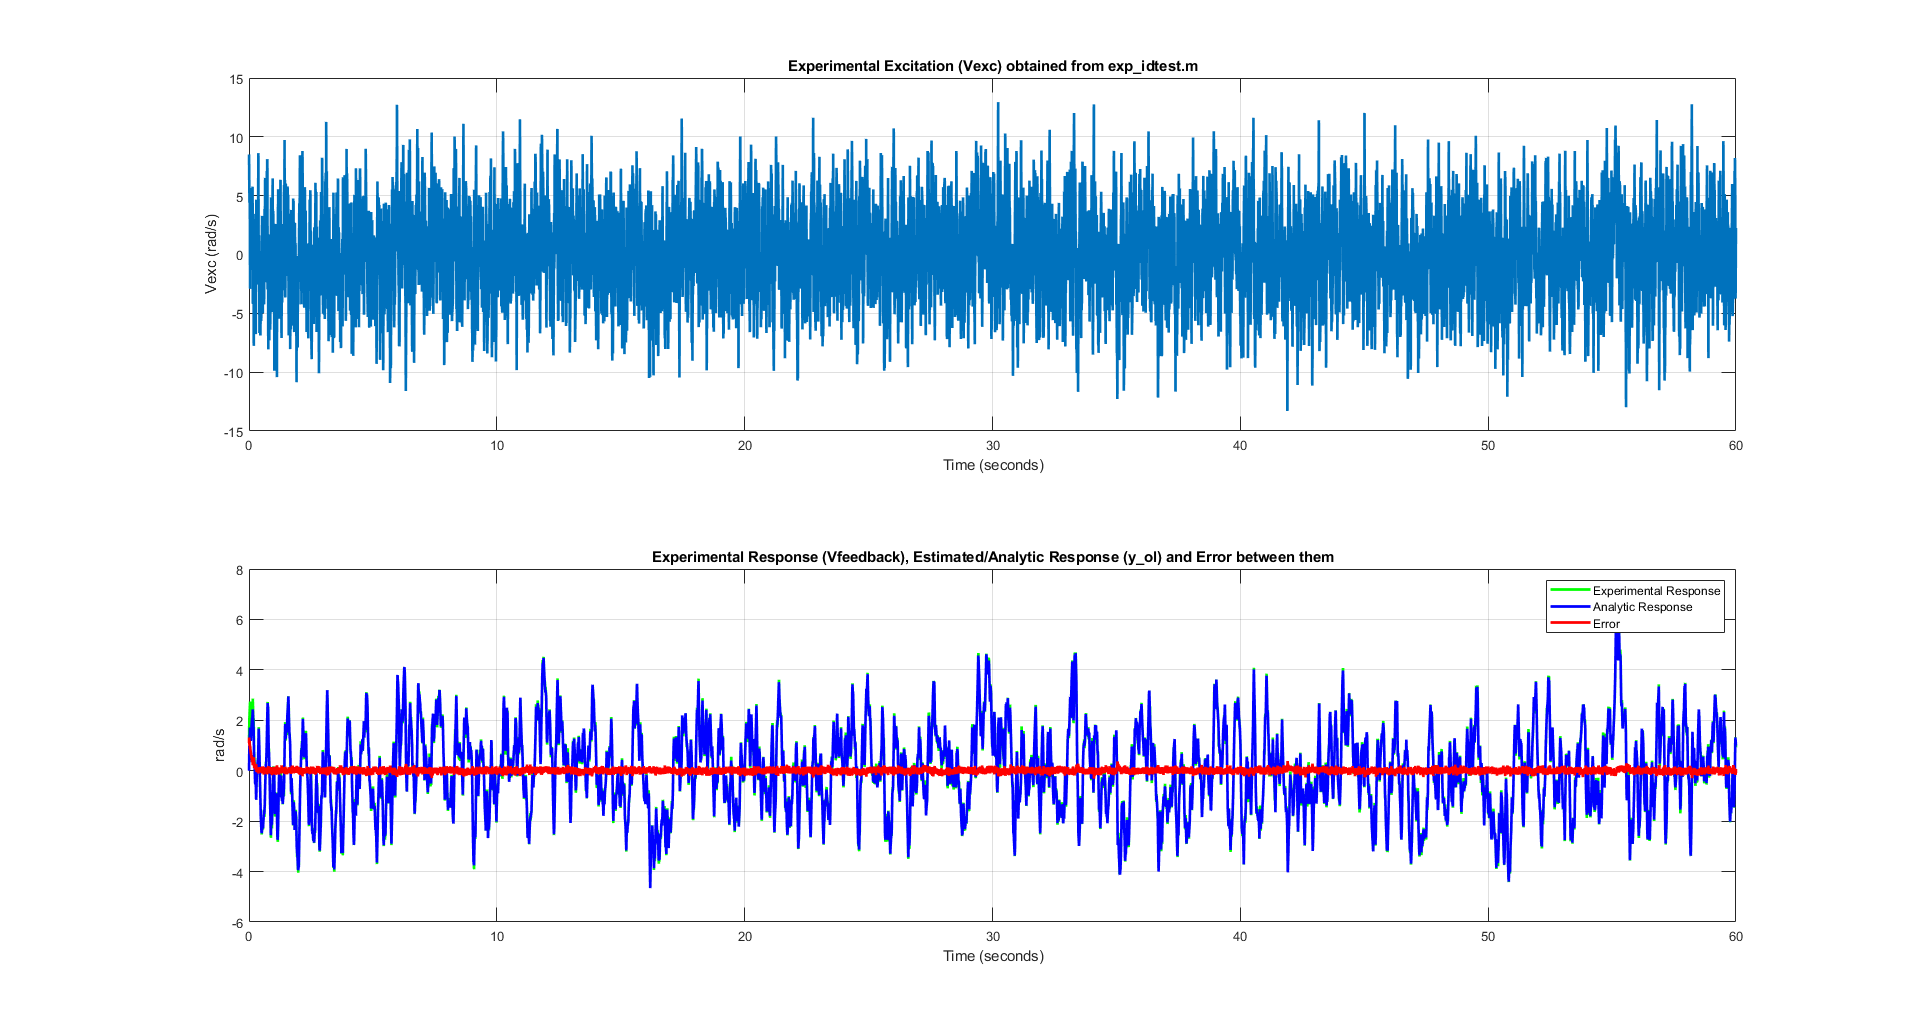

% 2a

% Importing the Experimental excitation 'Vexc' and response 'Vfeedback' from the file "exp_idtest.mat"
load('exp_idtest.mat');

% 2b
% Applying Experimental excitation to our complete open loop plant to
% obtain estimated response
[y_ol,t_ol,x_ol] = lsim(plant,Vexc,t);
% Error between Experimental feedback (Vfeedback) and Estimated/Analytic Response (y_ol)
Error = Vfeedback - y_ol';

% 2c
% Plotting

figure()
% Construct the 1st plot of just Experimental Excitation (Vexc)
subplot(2,1,1)
plot(t,Vexc);
grid on
title('Experimental Excitation (Vexc) obtained from exp_idtest.m','Interpreter','none');
xlabel('Time (seconds)');
ylabel('Vexc (rad/s)');
% xlim([0 numel(t)]);
 
% Construct the 2nd Plot of Experimental response, Analytic Response ()
subplot(2,1,2)
plot(t,Vfeedback,'g');
hold on
grid on
plot(t,y_ol, 'b');
plot(t,Error, 'r');
title('Experimental Response (Vfeedback), Estimated/Analytic Response (y_ol) and Error between them','Interpreter','none'); % 'interpreter', 'none' is to tell software to not interpret the Tex commands like _ as underscore and all
xlabel('Time (seconds)')
ylabel('rad/s');
legend('Experimental Response','Analytic Response', 'Error');
% xlim([0 numel(t)]);
% ylim([-0.3 1]);
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

# Frequency Domain Validation

Matlab provides us with several FFT-based tools for estimating the frequency response function using time-domain excitation and response data.  These tools are based on the **Welch’s Periodogram method**, and use time-domain windowing and frequency domain averaging. 

Explanation of some code used further:

**x** is a vector of N time-domain excitation samples that was input to the plant 

**y** is a vector of N time-domain response samples caused by the excitation, but might also have uncorrelated noise in the response 

**nfft = 2^14**;                        The FFT block size, must be a power-of-2 

**window = nfft**;                   This selects a default Hanning time-domain window 

**noverlap = nfft/2**;              This selects a 50% overlap in blocks 

** [Txy, fr] = tfestimate(x,y,window,noverlap,nfft,fs); ** 

Finds a transfer function estimate, T`xy`, given an input signal, `x`, and an output signal, `y`.

**Txy** is a complex vector of the frequency response evaluated at frequencies **fr** 

**fr** is a vector of equally spaced frequencies from 0 Hz to (fs/2) Hz 

 **[Cxy, fr] = mscohere(x, y, window, noverlap, nfft, fs)**;  

**Cxy** is a real vector of the coherence evaluated at frequencies **fr** 

**Coherence** is a number between 0 and 1, where 0 means that the response is not correlated with the input, and 1 means that the response is completely correlated with the input

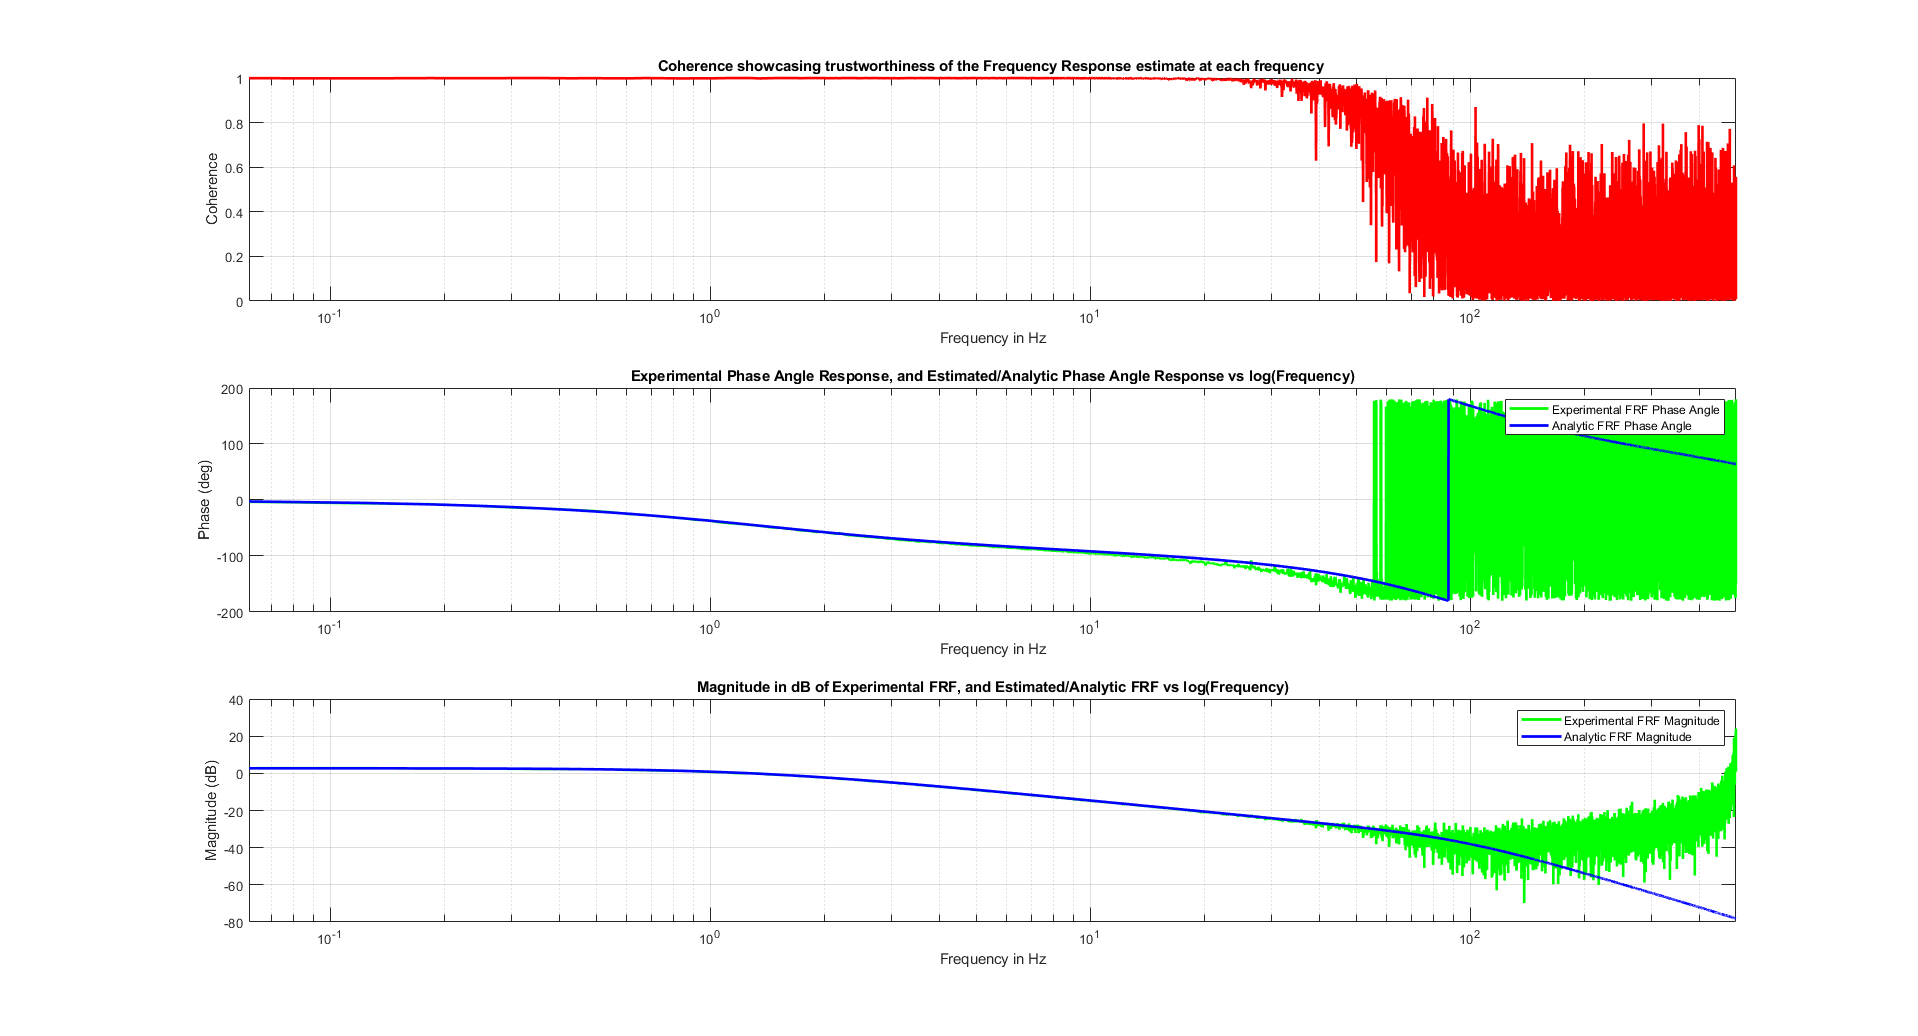

% 3a
% Parameters
nfft = 2^14;                                                        % The FFT block size of power of 2
window = nfft;                                                      % Selecting a default Hanning Time-domain window
noverlap = nfft/2;                                                  % Slecting 50% overlap in blocks

% Estimating the complex Frequency response of the overall plant Transfer
% Function using the experimental excitation and experimental response data
[Txy, fr] = tfestimate(Vexc, Vfeedback, window, noverlap, nfft, fs); 

% 3b
% Estimating Coherence between 0 (poor Coherence) and 1 (Perfect) showcasing trustworthiness of the Frequency Response estimate at each frequency
% using the experimental excitation and experimental response data
[Cxy, fr] = mscohere(Vexc, Vfeedback, window, noverlap, nfft, 1000); 

% 3c
% Computing Complex Frequency Response of Analytic plant transfer function
% given the Open loop model plant. 

% Note: this is our analytical FRF
Freq_Response_plant = freqresp(plant, 2*pi*fr, 'rad/s');                        % Need to input frequency vector in rad/s which is (w = 2*pi*fr [radians/sec])
Freq_Response_plant_squeezed = squeeze(Freq_Response_plant);                    % Remove dimensions of length 1
% Converting to degrees
Freq_Response_plant_Magnitude_dB = mag2db(abs(Freq_Response_plant_squeezed));   % Calculating magnitude of Complex frequency response in decibels
Freq_Response_plant_Phase = angle(Freq_Response_plant_squeezed);                % Calculating Phase angle of Complex frequency response in radians    
Freq_Response_plant_Phase = rad2deg(Freq_Response_plant_Phase);                 % Converting radians to degrees for plot


% Note: this is our experimental FRF
% Extra conversions for plotting the Bode plot
Freq_Response_Magnitude_dB = mag2db(abs(Txy));      % Calculating magnitude of Complex frequency response in decibels
Freq_Response_Phase = angle(Txy);                   % Calculating Phase angle of Complex frequency response in radians
Freq_Response_Phase = rad2deg(Freq_Response_Phase); % Converting radians to degrees for plot


% 3d
% Plotting the Bode Plot

figure()
% Construct the 1st plot of Coherence
subplot(3,1,1)
semilogx(fr, Cxy, 'r'); % Because we want the log x axis in plot
grid on
title('Coherence showcasing trustworthiness of the Frequency Response estimate at each frequency ','Interpreter','none');
xlabel('Frequency in Hz');
ylabel('Coherence');
xlim([0 500]);
 
% Construct the 2nd Plot of Experimental response, Analytic Response ()
subplot(3,1,2)
semilogx(fr, Freq_Response_Phase,'g');
hold on
grid on
semilogx(fr, Freq_Response_plant_Phase,'b');
title('Experimental Phase Angle Response, and Estimated/Analytic Phase Angle Response vs log(Frequency)','Interpreter','none'); % 'interpreter', 'none' is to tell software to not interpret the Tex commands like _ as underscore and all
xlabel('Frequency in Hz')
ylabel('Phase (deg)');
legend('Experimental FRF Phase Angle','Analytic FRF Phase Angle');
xlim([0 500]);
% ylim([-0.3 1]);
hold off

subplot(3,1,3)
semilogx(fr, Freq_Response_Magnitude_dB,'g');
hold on
grid on
semilogx(fr, Freq_Response_plant_Magnitude_dB,'b');
title('Magnitude in dB of Experimental FRF, and Estimated/Analytic FRF vs log(Frequency)','Interpreter','none'); % 'interpreter', 'none' is to tell software to not interpret the Tex commands like _ as underscore and all
xlabel('Frequency in Hz')
ylabel('Magnitude (dB)');
legend('Experimental FRF Magnitude','Analytic FRF Magnitude');
xlim([0 500]);
% ylim([-0.3 1]);
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

So we can see that we have a good coeherence up until Frequency of 1.5e1 Hz and thus in that range out Estimated FRF matches the Experimental FRF

# Tracking a Desired Reference

### **Closed-Loop Objective**: To track a periodic reference signal

## **Performance requirements:**

- 2% Settling time for a unit step $\le$ 1 second

- Percent Overshoot for a unit step $\le$ 15%

- Absolute Steady-State Error for a unit step $=$ 0 Volts

- Absolute Steady-State Error for a unit ramp $\le$ 0.2 Volts

- Absolute Peak Control Signal $\le$ 10 Volts $\Rightarrow |u\left(t\right)|\le 10\;V$

- Absolute Peak Response Signal $\le$ 10 Volts $\Rightarrow \left|y\left(t\right)\right|\le 10\;V$

- Absolute Peak Error Response Signal $\le$ 5.2 Volts $\Rightarrow \left|e\left(t\right)\right|\le 5\ldotp 2\;V$

- Gain Margin $\ge$ +6 dB

- Phase Margin $\ge$ +${45}^o$

- Phase Crossover Frequncy $\ge$ Gain Crossover Frequency

- Pole and Zero Frequencies $\le$  500 Hz

- Closed Loop (-3dB) Bandwidth $\ge$ 1 Hz

- Normalized Integrated Squared Error (ISE) minimized

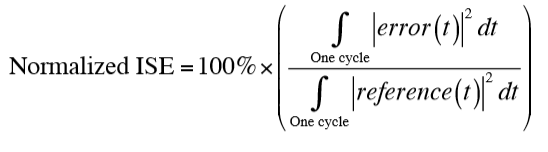

# Compensator Design

A controller is an element whose role is to maintain a physical quantity in a desired level. For exemple we have a Temperature controller, pH controller, speed control, PID controller. In other words, aim of controller design is to reduce the error between the reference and the output signal which is feedback to the controller with input (reference) signal.

**A compensator** : modification of system dynamics, to improve characteristics of the open-loop plant so that it can safely be used with feedback control. For exemple to improve stability, uncouple a system, to a 'lead/lag compensator, phase compensator. In case of Lead and Lag compensator which are often designed to satisfy phase and gain margins, these bode plot of the system itself changes after the insertion of compensator, bode plot indirectly represents system dynamics.

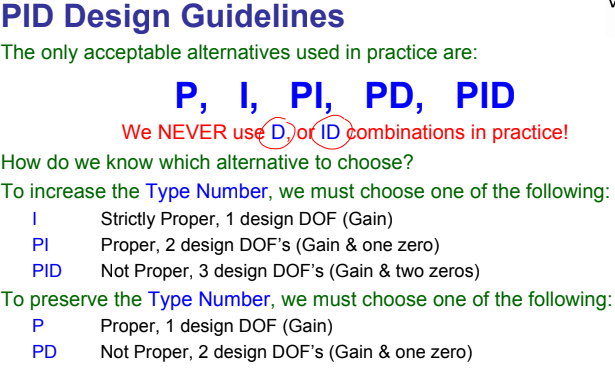

## Proportional Compensator

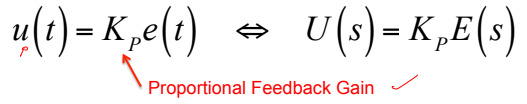

For **Proportional gain of 1.999** is able to satisfy all Performance reqirements except for zeroing out the Steady State error for Unit Step Response and Unit Ramp response, I also wanted to make sure I do go beyond the saturation point of control signal which is 10, and thus not feasible in reality.

%% Part 1: Maximum proportional feedback gain that meets all performance requirements

num_proportional = [1.999]; 
den_proportional = [1]; 

% Automated design Analysis tool to check the compensator
my_proportional_controller = tf(num_proportional,den_proportional)


my_proportional_controller =
 
  1.999
 
Static gain.



---------Controller Design Summary---------
Transfer Function Representation of Controller:

ans =
 
  1.999
 
Static gain.

Zero-Pole-Gain Representation of Controller:

ans =
 
  1.999
 
Static gain.



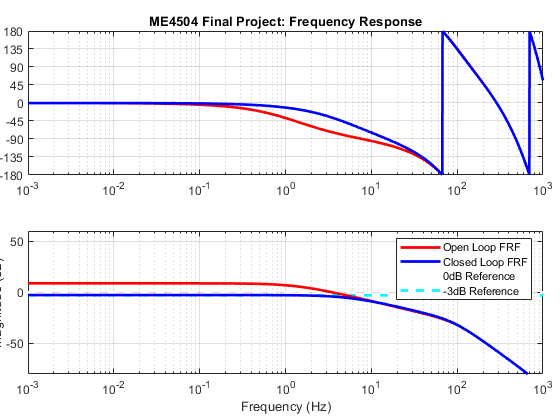

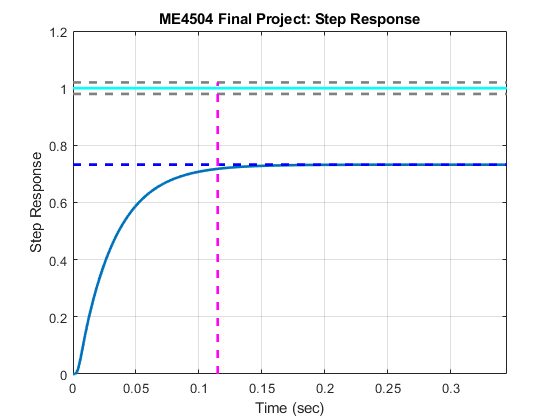

 
---------Closed Loop Performance Summary---------
 
  2% Settling Time for Unit Step (s):  Max=1, Actual=0.114848 (Meets requirement)

            %Overshoot for Unit Step:  Max=15, Actual=0.00310484 (Meets requirement)

Steady-State Error for Unit Step (V):  Max=0, Actual=0.267525 (DOES NOT MEET REQUIREMENT)

Steady-State Error for Unit Ramp (V):  Max=0.2, Actual=Inf (DOES NOT MEET REQUIREMENT)

    Peak Absolute Control Signal (V):  Max=10, Actual=9.995 (Meets requirement)

          Peak Absolute Response (V):  Max=10, Actual=3.66277 (Meets requirement)

    Peak Absolute Error Response (V):  Max=5.2, Actual=5 (Meets requirement)

                    Gain Margin (dB):  Min=6, Actual=26.0897 (Meets requirement)

                  Phase Margin (deg):  Min=45, Actual=107.034 (Meets requirement)

       Gain Crossover Frequency (Hz):  Max=67.2964, Actual=3.48173 (Meets requirement)

      Phase Crossover Frequency (Hz):  Min=3.48173, Actual=67.2964 (Meets requirement)

     Pole & Zer

eval_controller(my_proportional_controller)

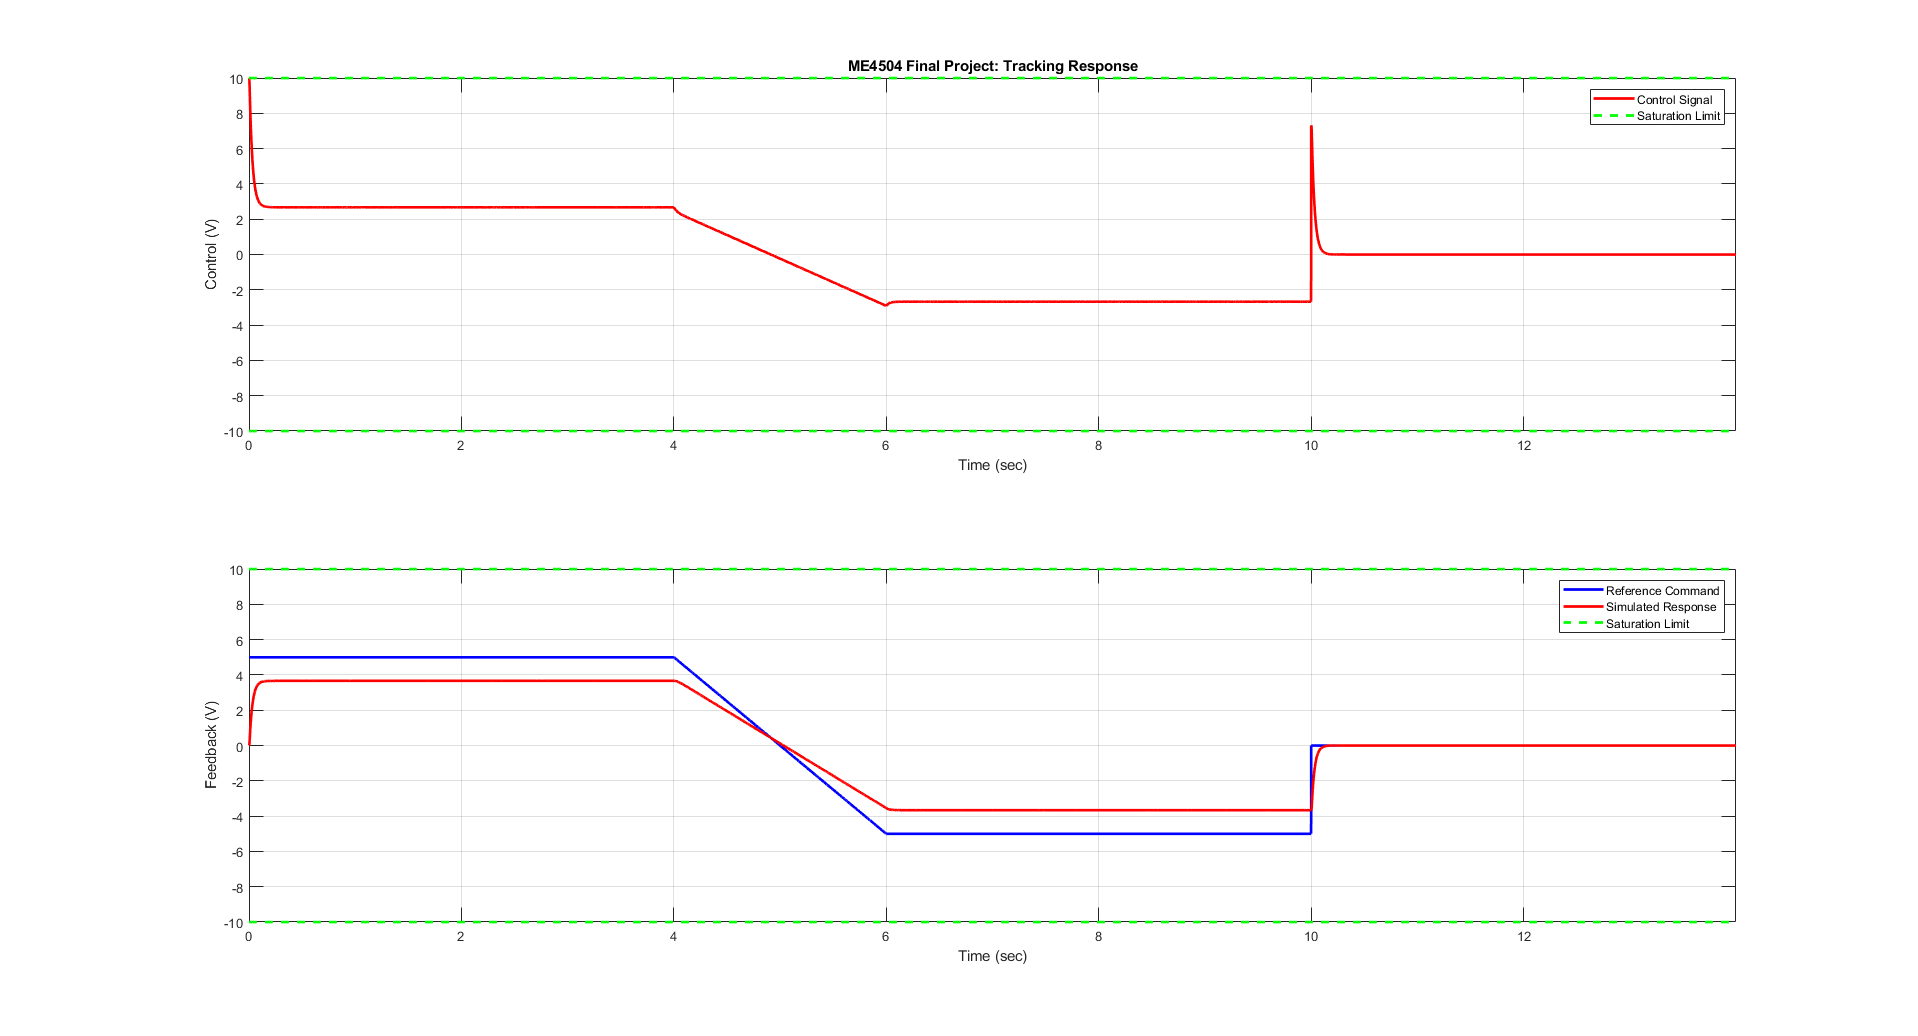

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## Integral Compensator

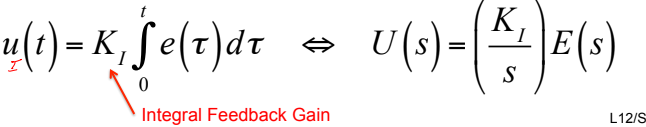

Integral Compensator with gain of 4.2242 met all the performance requirements

% An Integral compensator that can meet all of the performance requirements
% A lead compensator is a device that provides phase lead in its frequency response.
% In a lead compensator, |z|<|p|
k_i = 4.2242;
num_integral = [k_i]; 
den_integral = [1 0]; 
my_integral_controller = tf(num_integral,den_integral)


my_integral_controller =
 
  4.224
  -----
    s
 
Continuous-time transfer function.



---------Controller Design Summary---------
Transfer Function Representation of Controller:

ans =
 
  4.224
  -----
    s
 
Continuous-time transfer function.

Zero-Pole-Gain Representation of Controller:

ans =
 
  4.2242
  ------
    s
 
Continuous-time zero/pole/gain model.



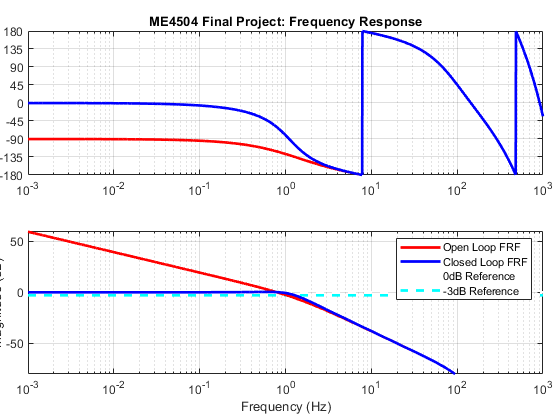

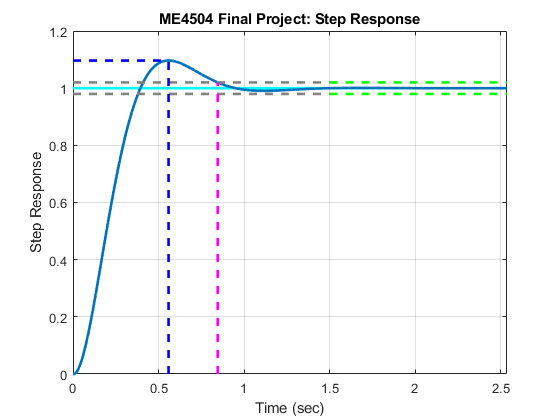

 
---------Closed Loop Performance Summary---------
 
  2% Settling Time for Unit Step (s):  Max=1, Actual=0.845919 (Meets requirement)

            %Overshoot for Unit Step:  Max=15, Actual=9.67239 (Meets requirement)

Steady-State Error for Unit Step (V):  Max=0, Actual=0 (Meets requirement)

Steady-State Error for Unit Ramp (V):  Max=0.2, Actual=0.172838 (Meets requirement)

    Peak Absolute Control Signal (V):  Max=10, Actual=4.23069 (Meets requirement)

          Peak Absolute Response (V):  Max=10, Actual=5.484 (Meets requirement)

    Peak Absolute Error Response (V):  Max=5.2, Actual=5 (Meets requirement)

                    Gain Margin (dB):  Min=6, Actual=33.8829 (Meets requirement)

                  Phase Margin (deg):  Min=45, Actual=58.7852 (Meets requirement)

       Gain Crossover Frequency (Hz):  Max=7.82951, Actual=0.795769 (Meets requirement)

      Phase Crossover Frequency (Hz):  Min=0.795769, Actual=7.82951 (Meets requirement)

     Pole & Zero freq. in range (H


% Automated design Analysis tool to check the compensator
eval_controller(my_integral_controller)

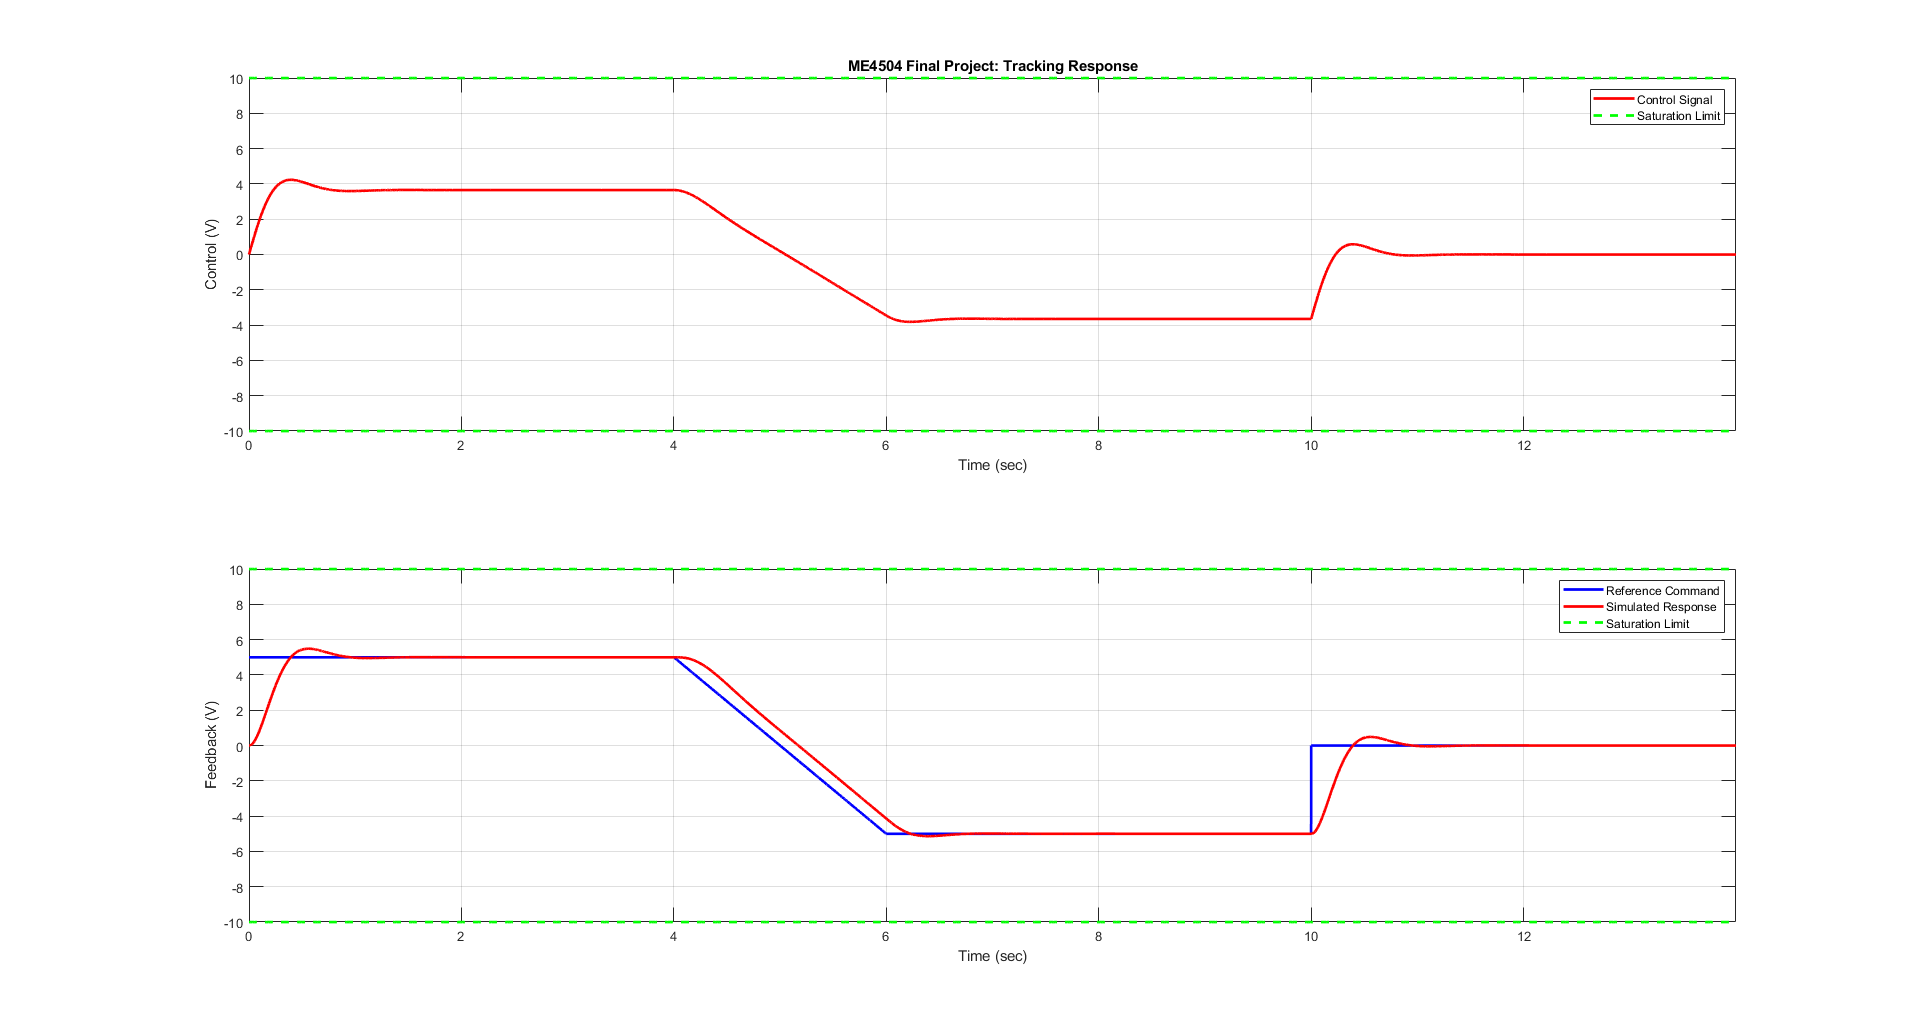


% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## PI Compensator

PI Compensator with proportional gain of 0.815 and Intergral gain of 19.2 met all the performance requirements

% A PI compensator that can meet all of the performance requirements
k_p = 0.815;
k_i = 19.2;
num_PI = [k_p k_i]; 
den_PI = [1 0]; 
my_controller_PI = tf(num_PI,den_PI)


my_controller_PI =
 
  0.815 s + 19.2
  --------------
        s
 
Continuous-time transfer function.



---------Controller Design Summary---------
Transfer Function Representation of Controller:

ans =
 
  0.815 s + 19.2
  --------------
        s
 
Continuous-time transfer function.

Zero-Pole-Gain Representation of Controller:

ans =
 
  0.815 (s+23.56)
  ---------------
         s
 
Continuous-time zero/pole/gain model.



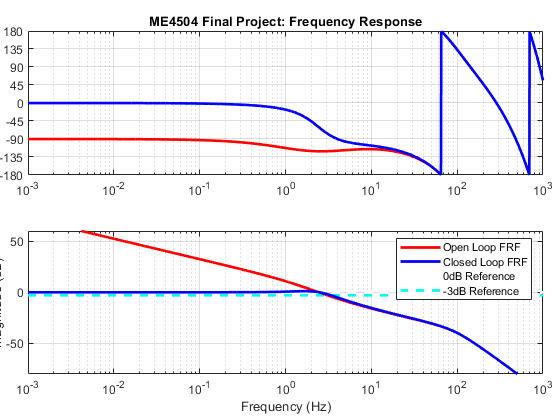

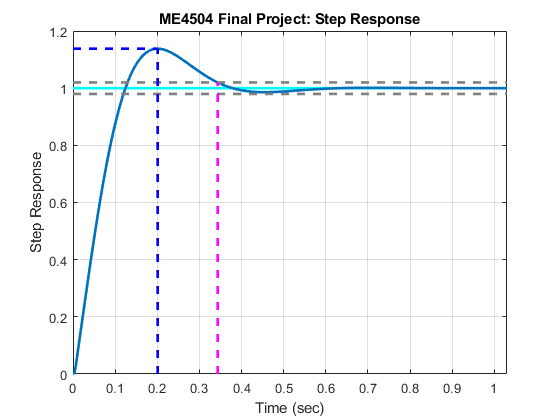

 
---------Closed Loop Performance Summary---------
 
  2% Settling Time for Unit Step (s):  Max=1, Actual=0.343345 (Meets requirement)

            %Overshoot for Unit Step:  Max=15, Actual=13.8059 (Meets requirement)

Steady-State Error for Unit Step (V):  Max=0, Actual=0 (Meets requirement)

Steady-State Error for Unit Ramp (V):  Max=0.2, Actual=0.0380262 (Meets requirement)

    Peak Absolute Control Signal (V):  Max=10, Actual=5.97674 (Meets requirement)

          Peak Absolute Response (V):  Max=10, Actual=5.69001 (Meets requirement)

    Peak Absolute Error Response (V):  Max=5.2, Actual=5 (Meets requirement)

                    Gain Margin (dB):  Min=6, Actual=33.4598 (Meets requirement)

                  Phase Margin (deg):  Min=45, Actual=59.2278 (Meets requirement)

       Gain Crossover Frequency (Hz):  Max=65.0474, Actual=2.44023 (Meets requirement)

      Phase Crossover Frequency (Hz):  Min=2.44023, Actual=65.0474 (Meets requirement)

     Pole & Zero freq. in range (

eval_controller(my_controller_PI)

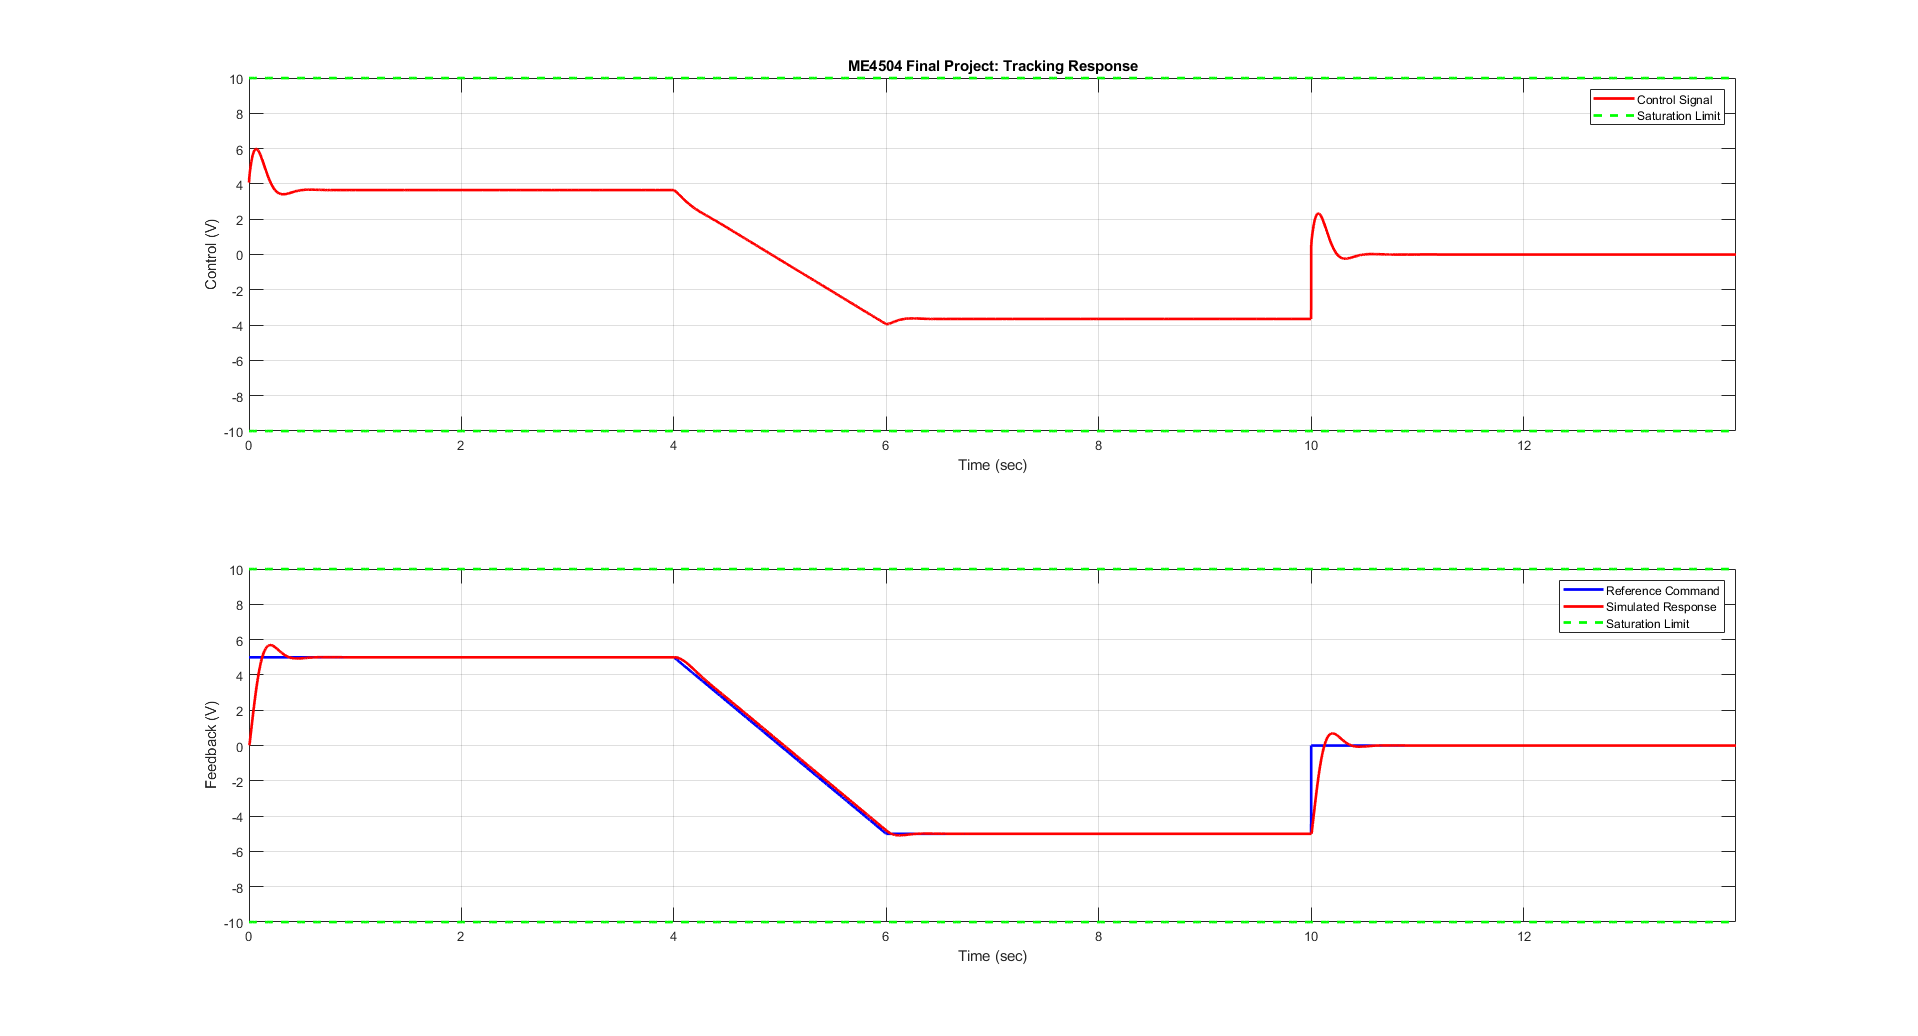


% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## PID Compensator

Transfer Function of an ideal PID Controller is:

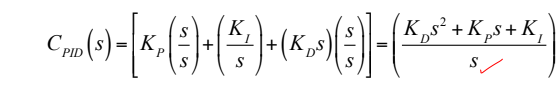

PID Compensator with proportional gain of 1.008, Intergral gain of 16.93  and Derivative gain of  met all the performance requirements

% A PID compensator that can meet all of the performance requirements
% my_controller_PID = pidtune(plant,'PID');
k_p = 1.008;
k_i = 16.93;
k_d = -1e-1000;
num_PID = [k_d k_p k_i]; 
den_PID = [1 0]; 
my_controller_PID = tf(num_PID,den_PID)


my_controller_PID =
 
  1.008 s + 16.93
  ---------------
         s
 
Continuous-time transfer function.



---------Controller Design Summary---------
Transfer Function Representation of Controller:

ans =
 
  1.008 s + 16.93
  ---------------
         s
 
Continuous-time transfer function.

Zero-Pole-Gain Representation of Controller:

ans =
 
  1.008 (s+16.8)
  --------------
        s
 
Continuous-time zero/pole/gain model.



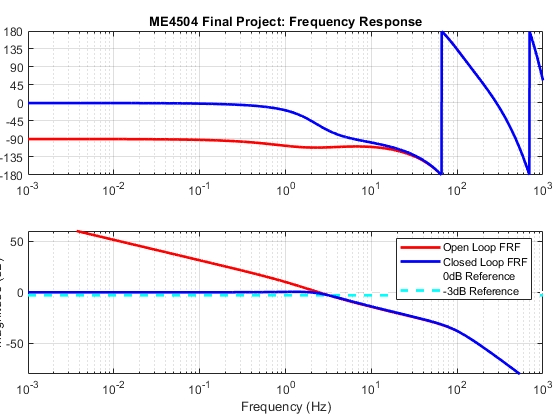

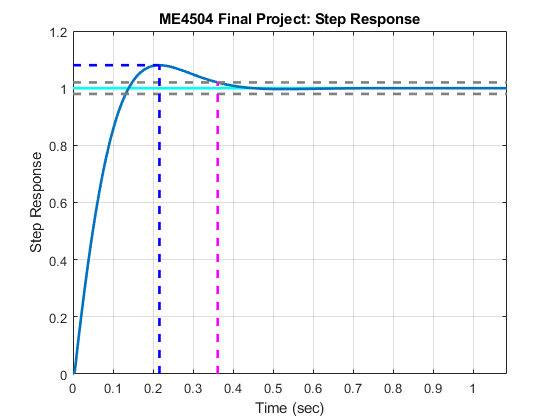

 
---------Closed Loop Performance Summary---------
 
  2% Settling Time for Unit Step (s):  Max=1, Actual=0.361602 (Meets requirement)

            %Overshoot for Unit Step:  Max=15, Actual=8.0255 (Meets requirement)

Steady-State Error for Unit Step (V):  Max=0, Actual=0 (Meets requirement)

Steady-State Error for Unit Ramp (V):  Max=0.2, Actual=0.0431249 (Meets requirement)

    Peak Absolute Control Signal (V):  Max=10, Actual=5.70826 (Meets requirement)

          Peak Absolute Response (V):  Max=10, Actual=5.40111 (Meets requirement)

    Peak Absolute Error Response (V):  Max=5.2, Actual=5.00001 (Meets requirement)

                    Gain Margin (dB):  Min=6, Actual=31.7411 (Meets requirement)

                  Phase Margin (deg):  Min=45, Actual=68.5635 (Meets requirement)

       Gain Crossover Frequency (Hz):  Max=65.7078, Actual=2.44165 (Meets requirement)

      Phase Crossover Frequency (Hz):  Min=2.44165, Actual=65.7078 (Meets requirement)

     Pole & Zero freq. in ra

eval_controller(my_controller_PID)

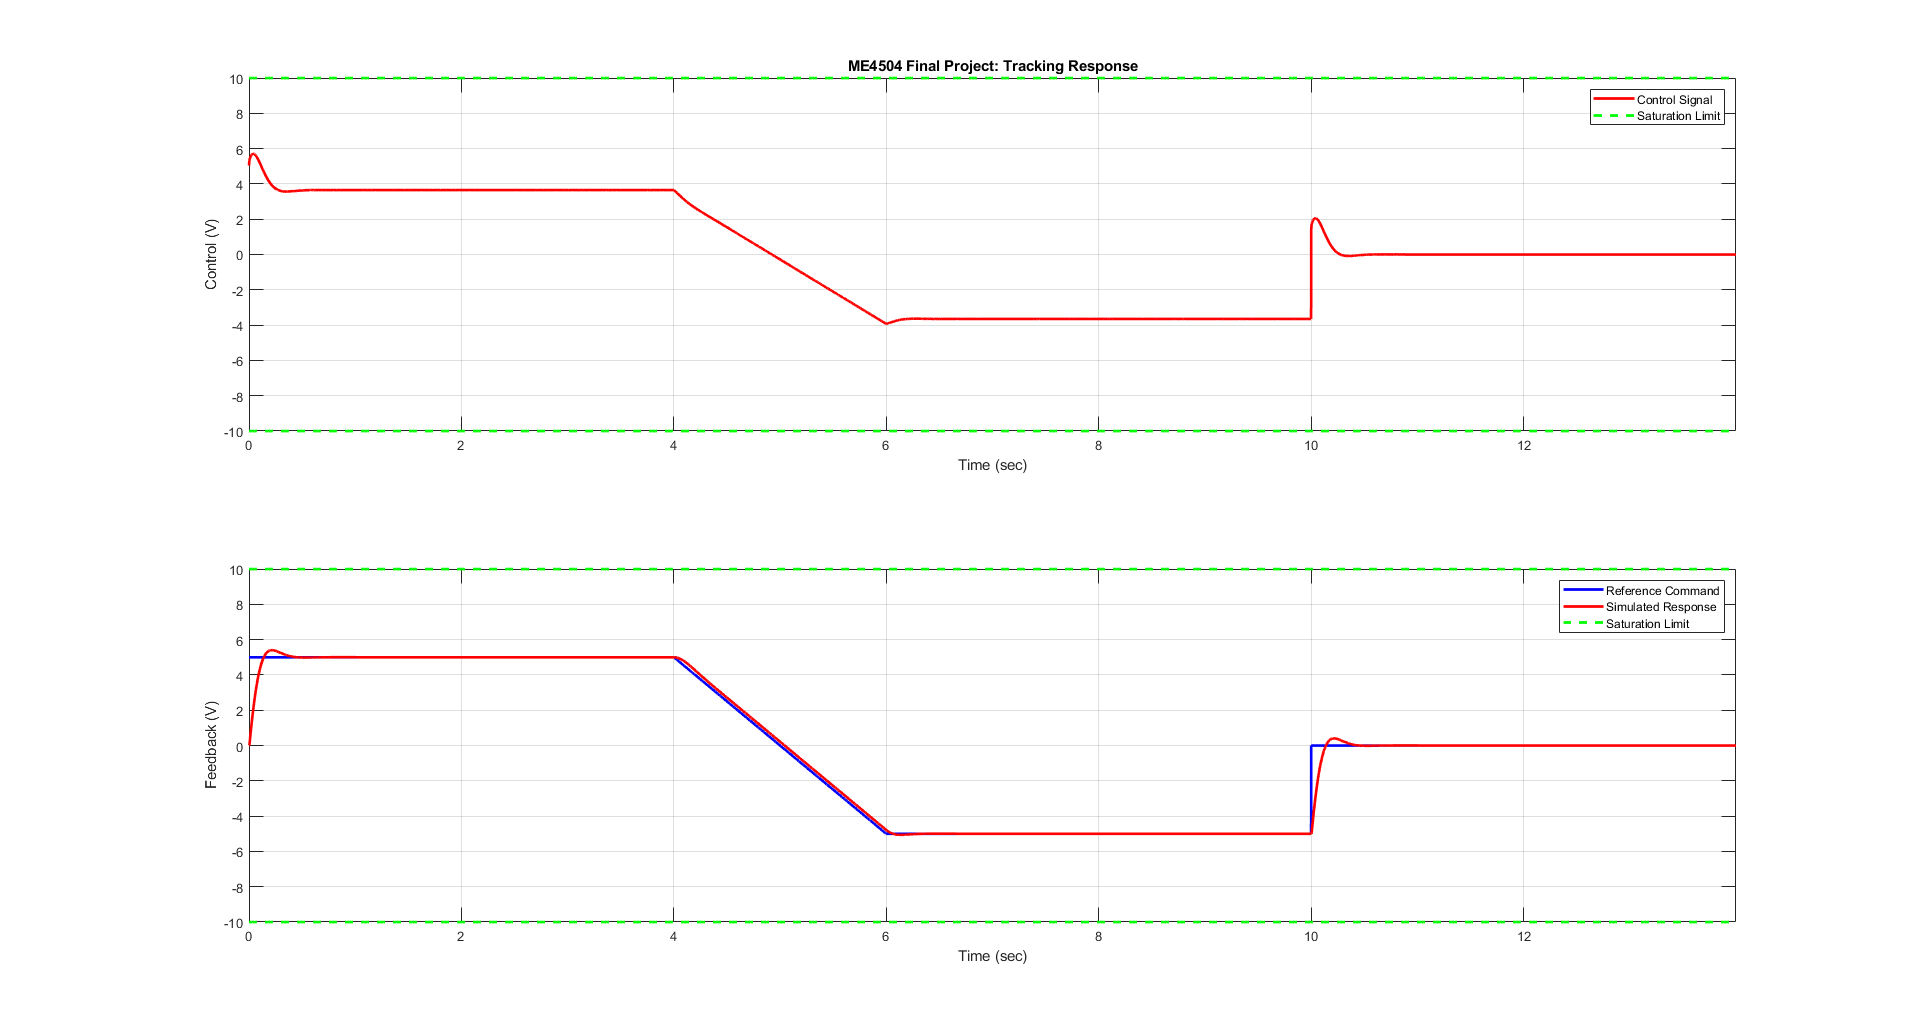

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## PIDF Compensator

Proportional, integral, and derivative with first-order filter on derivative term

% A PID compensator that can meet all of the performance requirements
my_controller_PIDF = pidtune(plant,'PIDF')


my_controller_PIDF =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 1.01, Ki = 16.8, Kd = -0.00158, Tf = 0.0458
 
Continuous-time PIDF controller in parallel form.



---------Controller Design Summary---------
Transfer Function Representation of Controller:

ans =
 
  0.9778 s^2 + 38.86 s + 366
  --------------------------
        s^2 + 21.82 s
 
Continuous-time transfer function.

Zero-Pole-Gain Representation of Controller:

ans =
 
  0.97784 (s+24.4) (s+15.34)
  --------------------------
         s (s+21.82)
 
Continuous-time zero/pole/gain model.



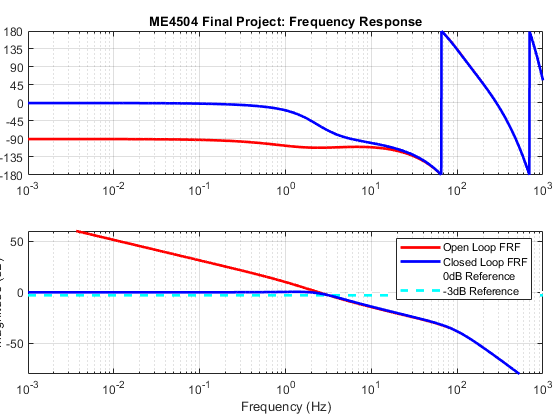

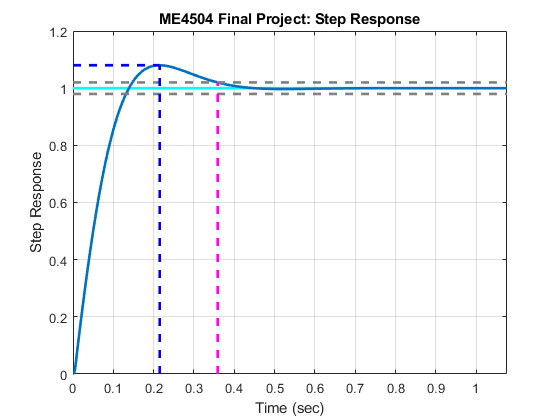

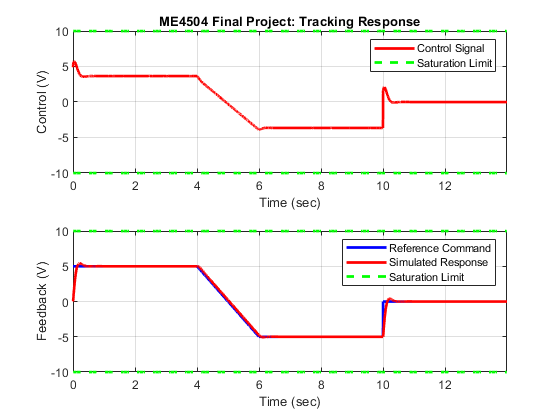

 
---------Closed Loop Performance Summary---------
 
  2% Settling Time for Unit Step (s):  Max=1, Actual=0.358836 (Meets requirement)

            %Overshoot for Unit Step:  Max=15, Actual=8.02152 (Meets requirement)

Steady-State Error for Unit Step (V):  Max=0, Actual=0 (Meets requirement)

Steady-State Error for Unit Ramp (V):  Max=0.2, Actual=0.0435147 (Meets requirement)

    Peak Absolute Control Signal (V):  Max=10, Actual=5.71178 (Meets requirement)

          Peak Absolute Response (V):  Max=10, Actual=5.40079 (Meets requirement)

    Peak Absolute Error Response (V):  Max=5.2, Actual=5 (Meets requirement)

                    Gain Margin (dB):  Min=6, Actual=31.9832 (Meets requirement)

                  Phase Margin (deg):  Min=45, Actual=68.1988 (Meets requirement)

       Gain Crossover Frequency (Hz):  Max=65.599, Actual=2.44134 (Meets requirement)

      Phase Crossover Frequency (Hz):  Min=2.44134, Actual=65.599 (Meets requirement)

     Pole & Zero freq. in range (Hz

eval_controller(my_controller_PIDF)

#### **Result**: The minimum Normalized ISE we could obtain was : 0.876% by PID controller

# Overall Comparison

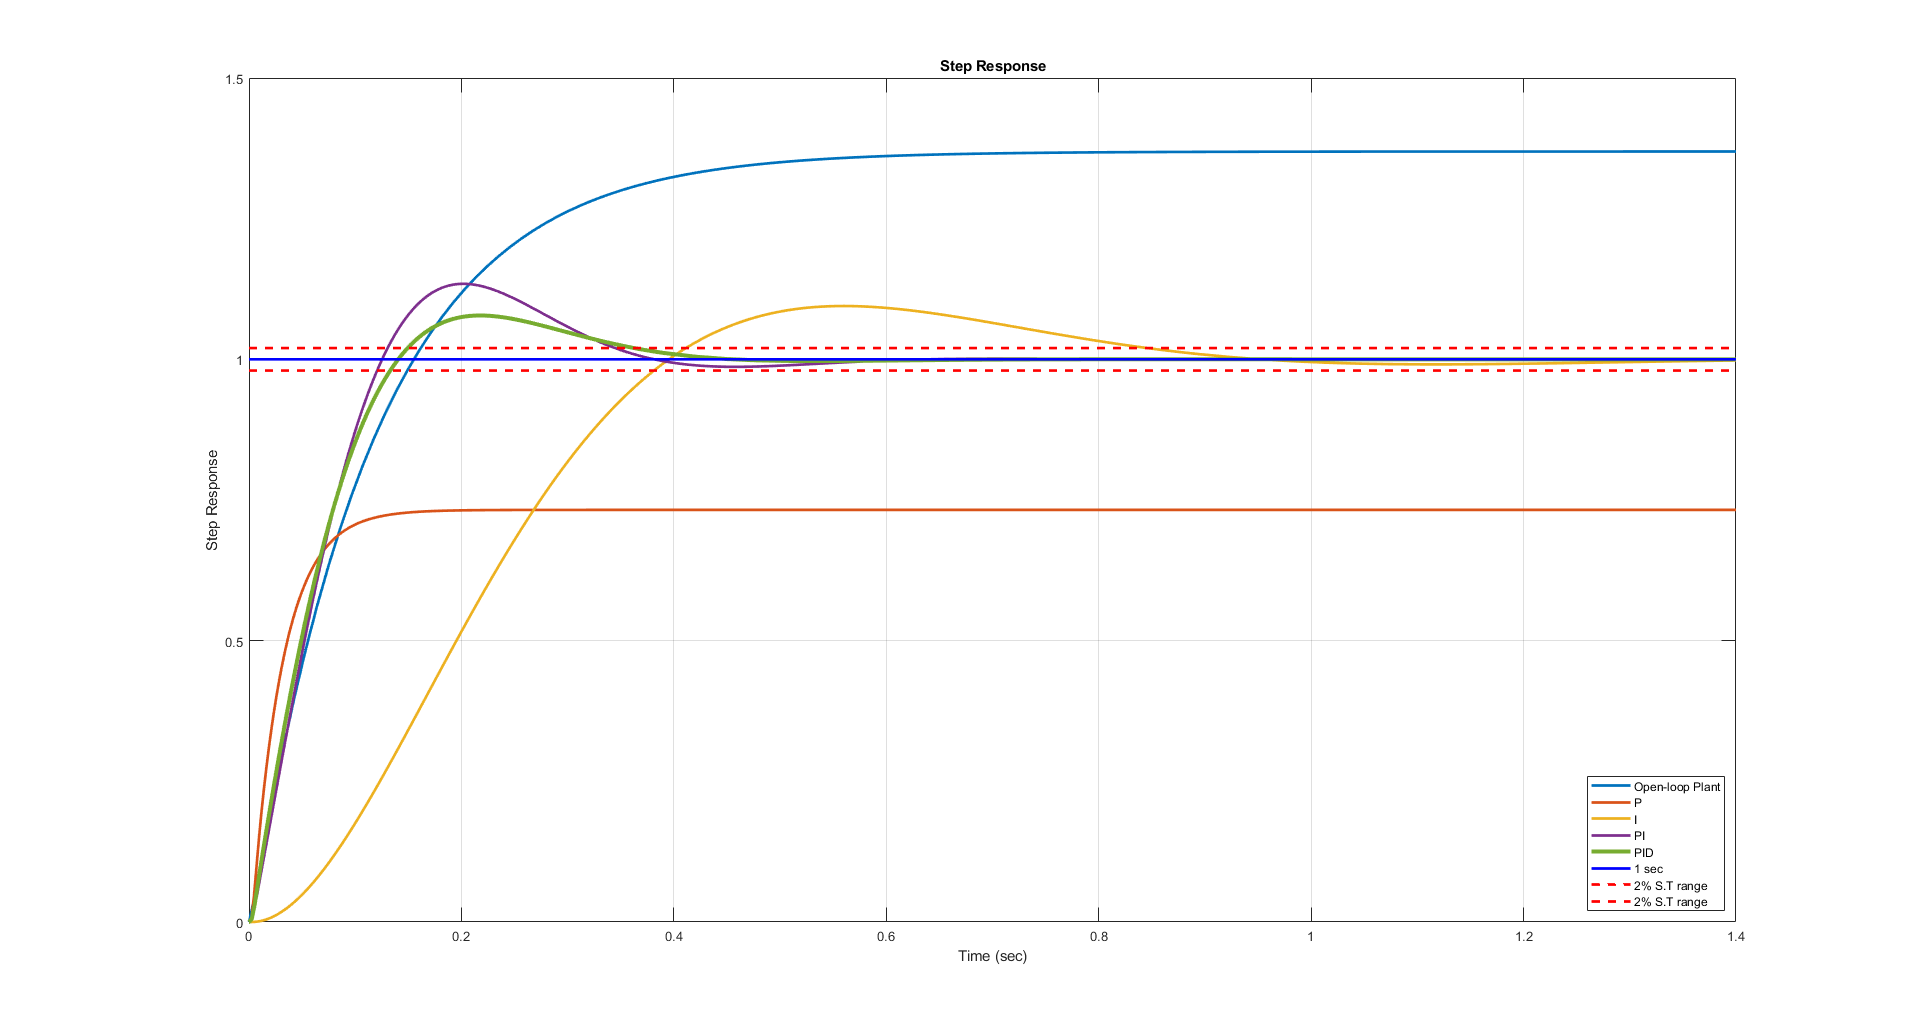

% First we should create a continous time P, I, PI, PID, and PIDF
% controllers in parallel form
% C = pid(Kp,Ki,Kd,Tf)

C_P = pid(num_proportional, 0, 0);
C_I = pid(0, num_integral, 0);
C_PI = pid(num_PI(1,1), num_PI(1,2), 0);
C_PID = pid(num_PID(1,2), num_PID(1,3), num_PID(1,1));

% Closed loop continous time transfer function
T_P = feedback(C_P*plant,1); % Closed loop system with +1 feedback
T_I = feedback(C_I*plant,1);
T_PI = feedback(C_PI*plant,1);
T_PID = feedback(C_PID*plant,1);

% S_P = stepinfo(T_P);

% The Control System Toolbox plot functions do not allow you to alter their properties easily, if at all.
[y_plant, t_plant] = step(plant,1.4); % Dataset For 2 seconds
[y_P, t_P] = step(T_P,1.4);
[y_I, t_I] = step(T_I, 1.4);
[y_PI, t_PI] = step(T_PI, 1.4);
[y_PID, t_PID] = step(T_PID, 1.4);


figure()
plot(t_plant, squeeze(y_plant), 'LineWidth', 2);
hold on
grid on
plot(t_P, squeeze(y_P), 'LineWidth', 2);
plot(t_I, squeeze(y_I), 'LineWidth', 2);
plot(t_PI, squeeze(y_PI), 'LineWidth', 2);
plot(t_PID, squeeze(y_PID), 'LineWidth', 3);


%  2% settling time refrence line
hRef1=refline(0,1);
set(hRef1,'color','b'); % Max horizontal
hRef2=refline(0,1.02);
set(hRef2,'color','r','linestyle','--'); % Max horizontal
hRef3=refline(0,0.98);
set(hRef3,'color','r','linestyle','--'); % Min horizontal
title('Step Response');
xlabel('Time (sec)');
ylabel('Step Response');
h = legend('Open-loop Plant', 'P', 'I', 'PI', 'PID', '1 sec', '2% S.T range', '2% S.T range');
set(h, 'Location','southeast');
ylim([0 1.5]);
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);